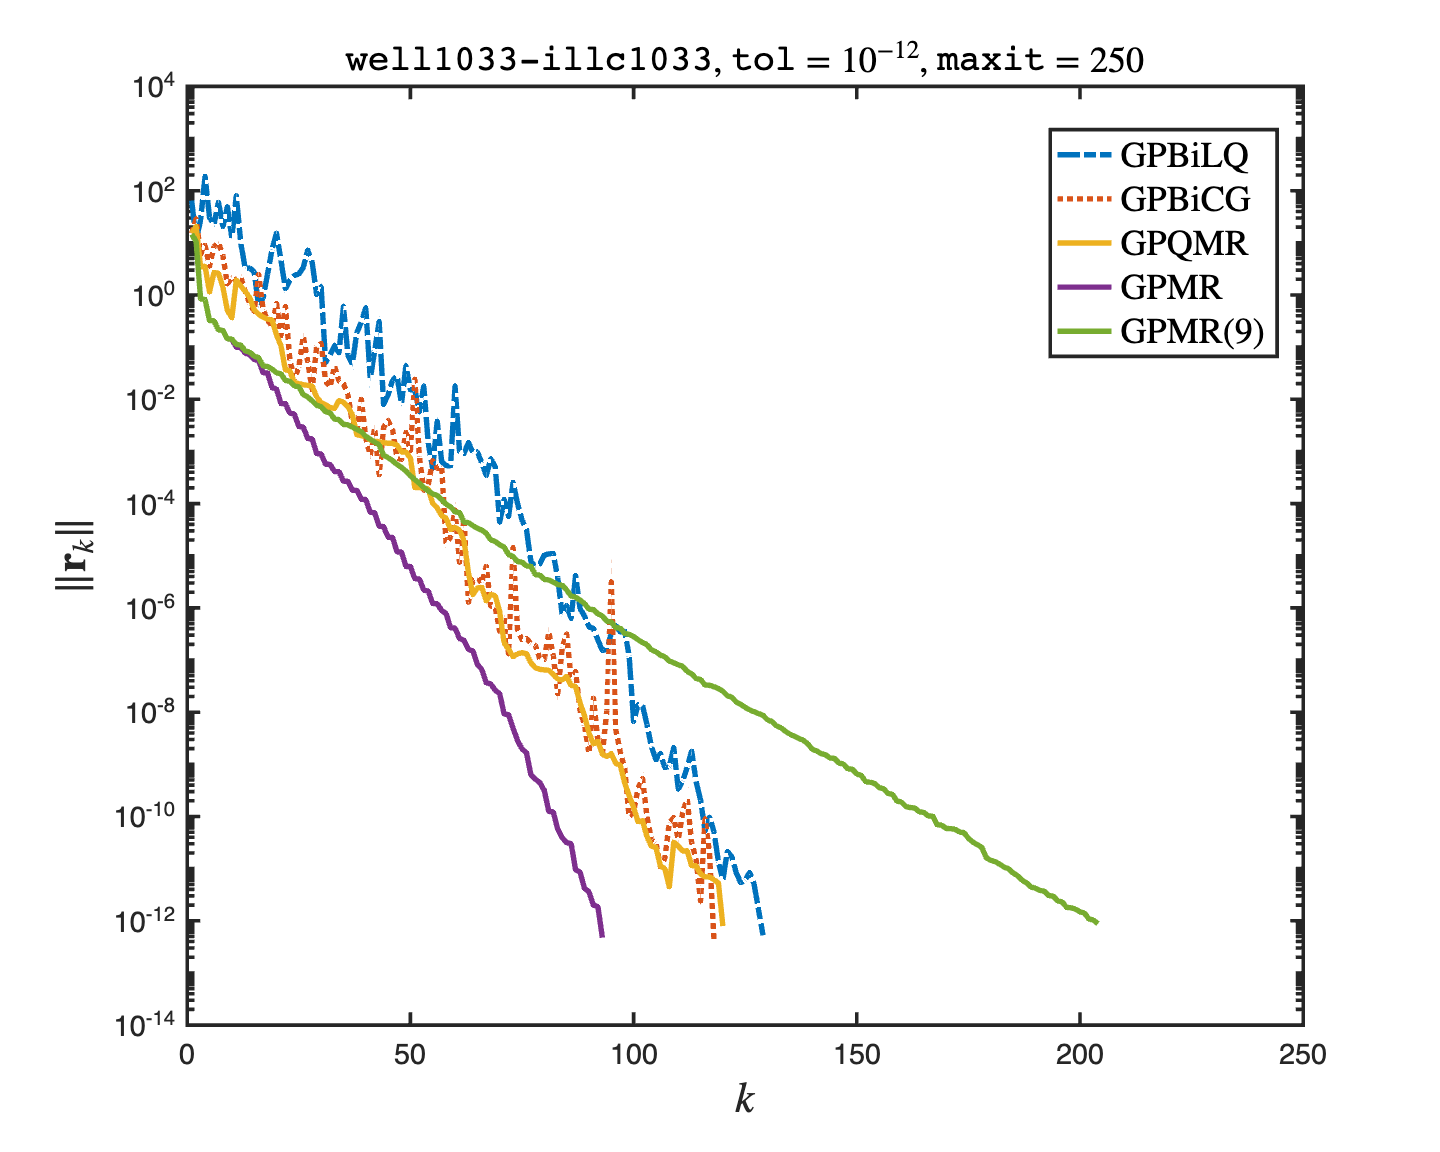

% Kui Du, Jia-Jun Fan, and Fang Wang 2024.1.4
clc; close all; clearvars;
load('data/well1033.mat');
A = Problem.A';
load('data/illc1033.mat');
B = Problem.A;

[m, n] = size(A);
lambda = 1; mu = -.1;
K = [lambda * speye(m), A; B, mu * speye(n)];
f = K * ones(m+n, 1);
b = f(1:m); c = f(m+1:end);

tol = 1e-12; maxit = 400; restart = 9;
[~, ~, ~, gpmr_res] = gpmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, gpmr_res_9] = gpmr(A, B, b, c, lambda, mu, tol, maxit, restart);
[~, ~, ~, gpqmr_res] = gpqmr(A, B, b, c, lambda, mu, tol, maxit); 
[~, ~, ~, gpbilq_res, gpbicg_res] = gpbilq(A, B, b, c, lambda, mu, tol, maxit);
gpbicg_res = gpbicg_res(1:find(gpbicg_res<tol,1));

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   16);
figure('Position',[180 120 800 640]);
semilogy(1:length(gpbilq_res), gpbilq_res, LineWidth=3, LineStyle="-.");
hold on;
semilogy(1:length(gpbicg_res), gpbicg_res, LineWidth=3, LineStyle=":");
semilogy(1:length(gpqmr_res), gpqmr_res, LineWidth=3);
semilogy(1:length(gpmr_res), gpmr_res, LineWidth=3);
semilogy(1:length(gpmr_res_9), gpmr_res_9, LineWidth=3);
hold off;

xlabel('$k$',Interpreter='latex',FontSize=24);
ylabel('$\|{\bf r}_k\|$', Interpreter='latex',FontSize=24);
legend('GPBiLQ', 'GPBiCG', 'GPQMR', 'GPMR', 'GPMR($9$)', Interpreter='latex', Location='best',FontSize=20);
title('{\tt well1033-illc1033}, ${\tt tol}=10^{-12}$, ${\tt maxit}=250$', Interpreter='latex',FontSize=20); 
print('fig1033','-depsc')

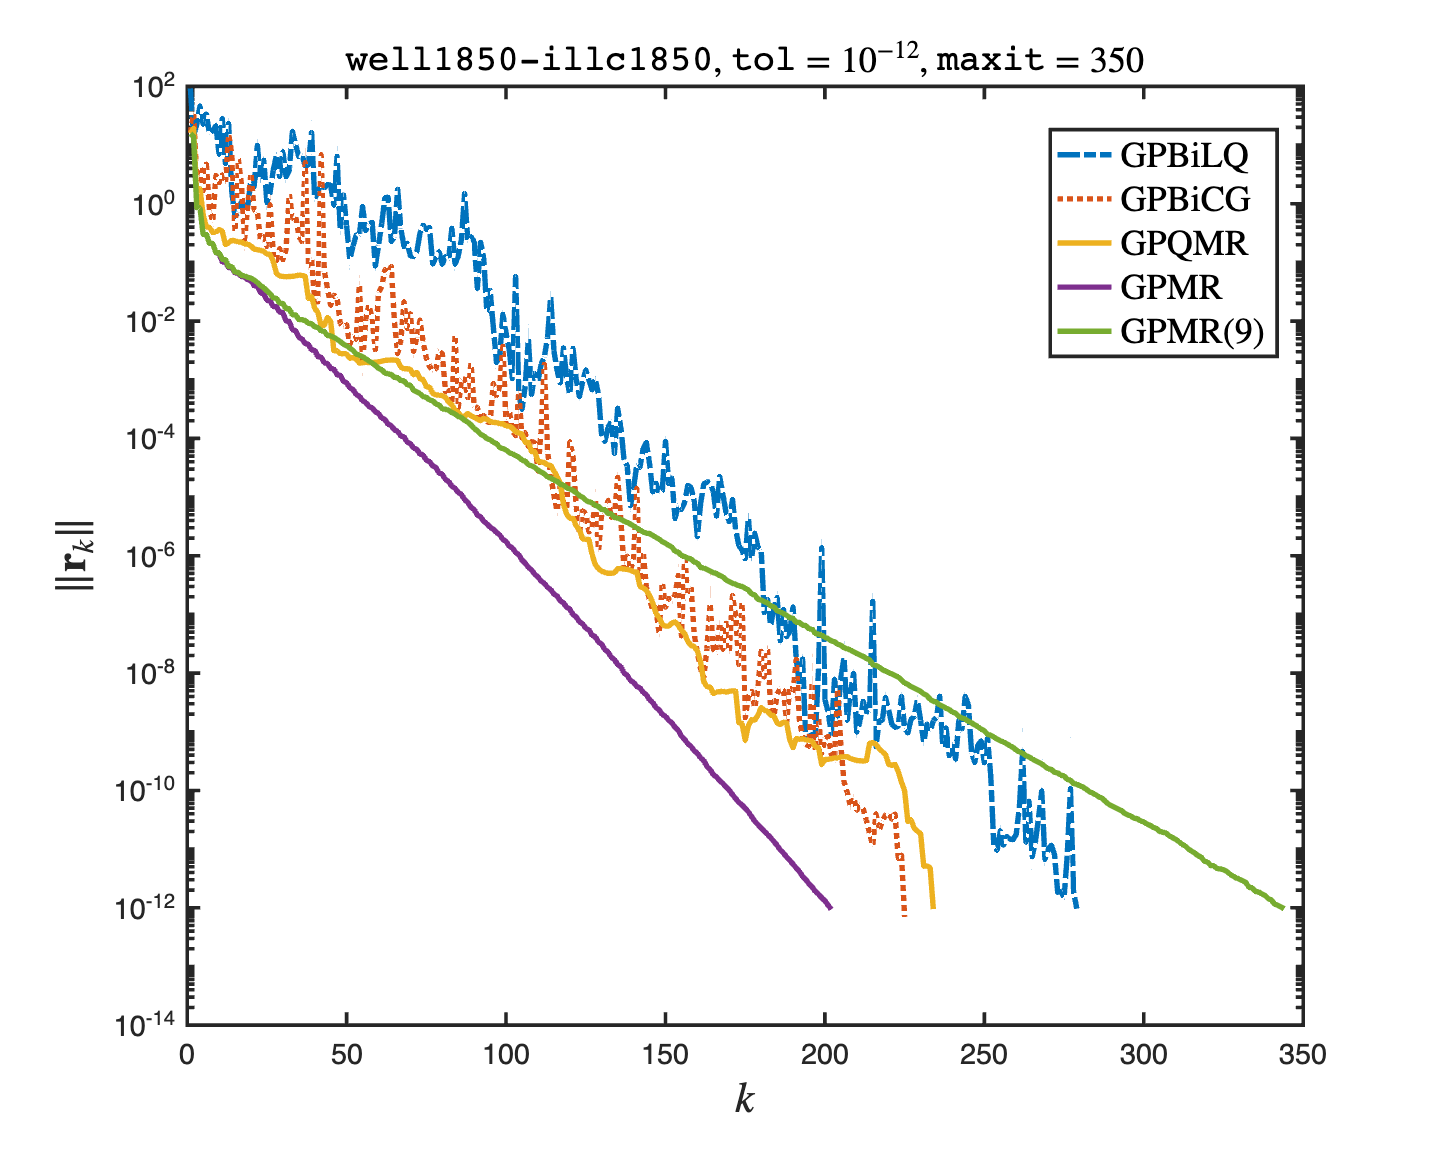

clc; close all; clearvars;
load('data/well1850.mat');
A = Problem.A';
load('data/illc1850.mat');
B = Problem.A;

[m, n] = size(A);
lambda = 1; mu = -.05;
K = [lambda * speye(m), A; B, mu * speye(n)];
f = K * ones(m+n, 1);
b = f(1:m); c = f(m+1:end);

tol = 1e-12; maxit = 400; restart = 9;
[~, ~, ~, gpmr_res] = gpmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, gpmr_res_9] = gpmr(A, B, b, c, lambda, mu, tol, maxit, restart);
[~, ~, ~, gpqmr_res] = gpqmr(A, B, b, c, lambda, mu, tol, maxit); 
[~, ~, ~, gpbilq_res, gpbicg_res] = gpbilq(A, B, b, c, lambda, mu, tol, maxit);
gpbicg_res = gpbicg_res(1:find(gpbicg_res<tol,1));

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   16);
figure('Position',[180 120 800 640]);
semilogy(1:length(gpbilq_res), gpbilq_res, LineWidth=3, LineStyle="-.");
hold on;
semilogy(1:length(gpbicg_res), gpbicg_res, LineWidth=3, LineStyle=":");
semilogy(1:length(gpqmr_res), gpqmr_res, LineWidth=3);
semilogy(1:length(gpmr_res), gpmr_res, LineWidth=3);
semilogy(1:length(gpmr_res_9), gpmr_res_9, LineWidth=3);
hold off;

xlabel('$k$',Interpreter='latex',FontSize=24);
ylabel('$\|{\bf r}_k\|$', Interpreter='latex',FontSize=24);
legend('GPBiLQ', 'GPBiCG', 'GPQMR', 'GPMR', 'GPMR($9$)', Interpreter='latex', Location='best',FontSize=20);
title('{\tt well1850-illc1850}, ${\tt tol}=10^{-12}$, ${\tt maxit}=350$', Interpreter='latex', FontSize=20);
print('fig1850','-depsc')

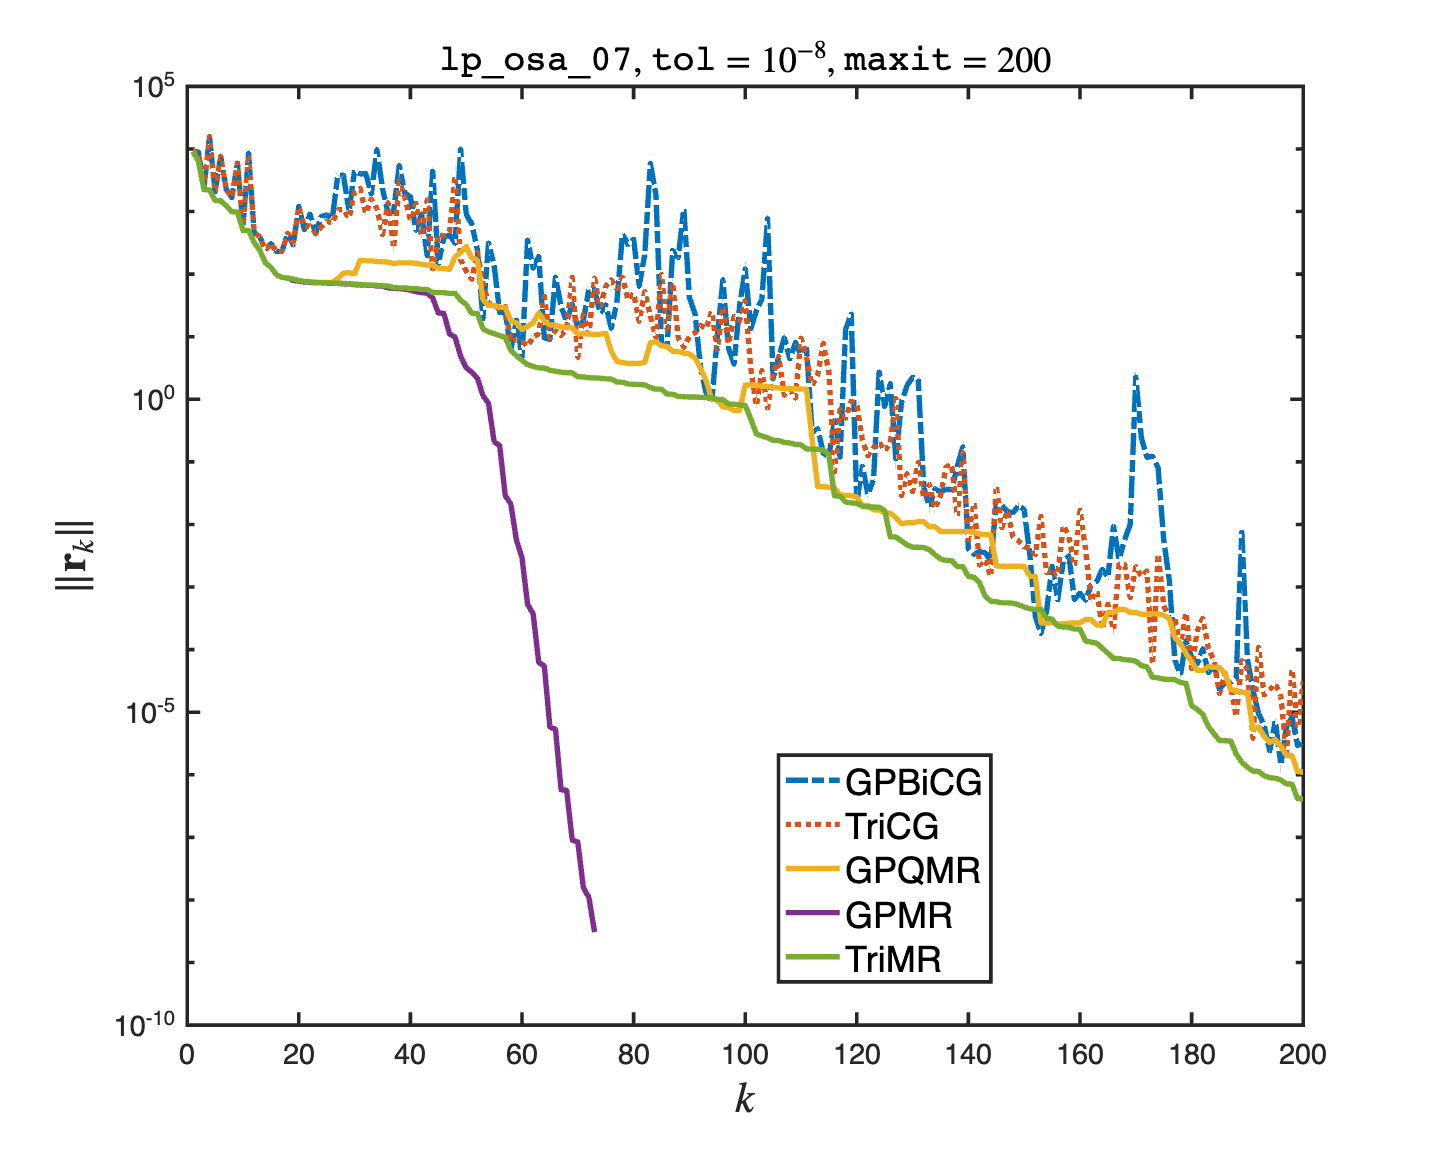

clc; close all; clearvars;
load('data/lp_osa_07.mat');
A = Problem.A;
B = A';

[m, n] = size(A);
lambda = 1; mu = -1;
K = [lambda * speye(m), A; B, mu * speye(n)];
f = K * ones(m+n, 1);
b = f(1:m); c = f(m+1:end);

tol = 1e-8; maxit = 200;
[~, ~, ~, gpmr_res] = gpmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, gpqmr_res] = gpqmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, ~, gpbicg_res] = gpbilq(A, B, b, c, lambda, mu, tol, maxit);
% gpbicg_res = gpbicg_res(1:find(gpbicg_res<tol,1));

[~, ~, ~, trimr_res] = trimr(A, b, c, lambda, mu, tol, maxit);
[~, ~, ~, tricg_res] = tricg(A, b, c, lambda, mu, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   16);
figure('Position',[180 120 800 640]);
semilogy(1:length(gpbicg_res), gpbicg_res, LineWidth=3, LineStyle="-.");
hold on;
semilogy(1:length(tricg_res), tricg_res, LineWidth=3, LineStyle=":");
semilogy(1:length(gpqmr_res), gpqmr_res, LineWidth=3);
semilogy(1:length(gpmr_res), gpmr_res, LineWidth=3);
semilogy(1:length(trimr_res), trimr_res, LineWidth=3);
hold off;

xlabel('$k$', Interpreter='latex', FontSize=24);
ylabel('$\|{\bf r}_k\|$', Interpreter='latex', FontSize=24);
legend('GPBiCG', 'TriCG', 'GPQMR', 'GPMR', 'TriMR', Location='best', FontSize=20);
title('{\tt lp\_osa\_07}, ${\tt tol}=10^{-8}$, ${\tt maxit}=200$', Interpreter='latex', FontSize=20);
print('figosa07','-depsc')

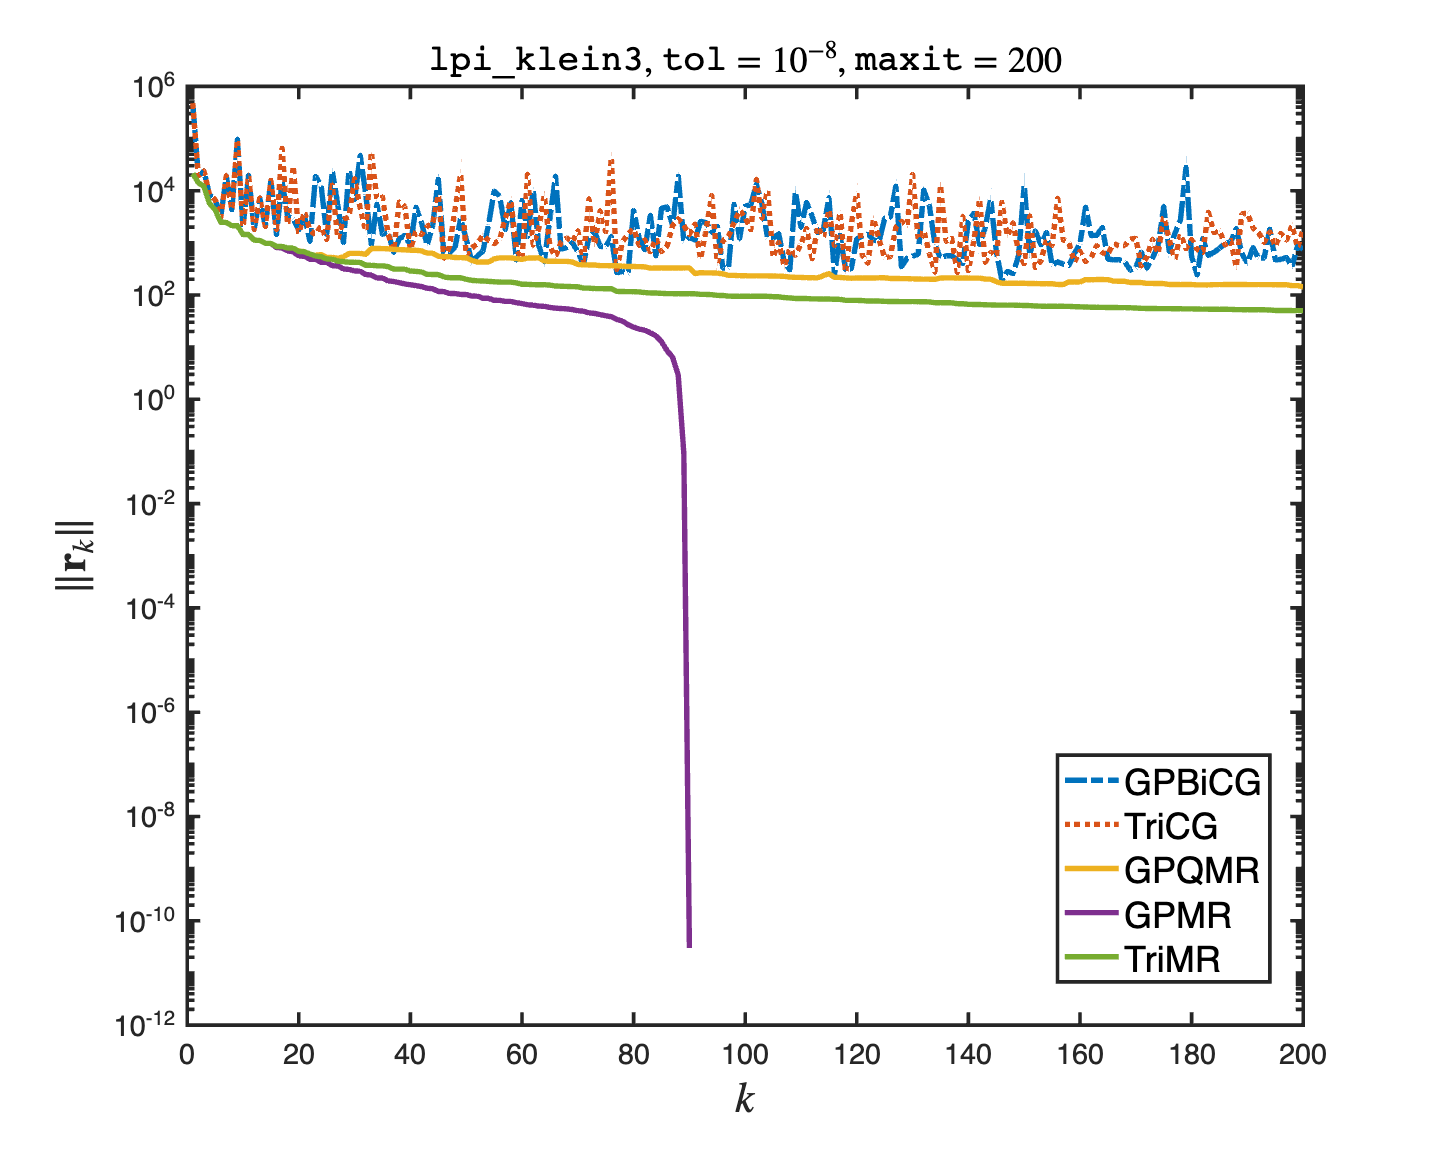

clc; close all; clearvars;

load('data/lpi_klein3.mat');
A = Problem.A;
B = A';

[m, n] = size(A);
lambda = 1; mu = -1;
K = [lambda * speye(m), A; B, mu * speye(n)];
f = K * ones(m+n, 1);
b = f(1:m); c = f(m+1:end);

tol = 1e-8; maxit = 200;
[~, ~, ~, gpmr_res] = gpmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, gpqmr_res] = gpqmr(A, B, b, c, lambda, mu, tol, maxit);
[~, ~, ~, ~, gpbicg_res] = gpbilq(A, B, b, c, lambda, mu, tol, maxit);

[~, ~, ~, trimr_res] = trimr(A, b, c, lambda, mu, tol, maxit);
[~, ~, ~, tricg_res] = tricg(A, b, c, lambda, mu, tol, maxit);

set(0, 'defaultaxeslinewidth',  2);
set(0, 'defaultaxesfontsize',   16);
figure('Position',[180 120 800 640]);
semilogy(1:length(gpbicg_res), gpbicg_res, LineWidth=3, LineStyle="-.");
hold on;
semilogy(1:length(tricg_res), tricg_res, LineWidth=3, LineStyle=":");
semilogy(1:length(gpqmr_res), gpqmr_res, LineWidth=3);
semilogy(1:length(gpmr_res), gpmr_res, LineWidth=3);
semilogy(1:length(trimr_res), trimr_res, LineWidth=3);
hold off;

xlabel('$k$', Interpreter='latex', FontSize=24);
ylabel('$\|{\bf r}_k\|$', Interpreter='latex', FontSize=24);
legend('GPBiCG', 'TriCG', 'GPQMR', 'GPMR', 'TriMR', Location='best', FontSize=20);
title('{\tt lpi\_klein3}, ${\tt tol}=10^{-8}$, ${\tt maxit}=200$', Interpreter='latex',FontSize=20);
print('figklein3','-depsc')

\